# ME5554/AOE5754/ECE5754 Applied Linear Systems

# Homework 1

Samuel Kramer

August 27th, 2023

This purpose of this homework is to refresh your basic understanding of some pre-requisite material:

- transfer functions

- closed-loop analysis

- Laplace transforms

- time-domain simulation

- linear algebra

Some of these problems can be completed in multiple ways.  You are welcome to use whichever way works best for you; however, this course is Matlab intensive, and you will be required to complete some future assignments using advanced tools such as LiveScripting and the Symbolic Toolbox.  If you are not comfortable using some of these Matlab tools, I highly recommend you spend time with the following:

Matlab LiveScript

- watch the Matlab LiveScript Tutorial video in the Course Gallery on Canvas (most important)

- [https://www.mathworks.com/products/matlab/live-editor.html](https://www.mathworks.com/products/matlab/live-editor.html)

Matlab Symbollic Toolbox

- see the symbolic_examplex.mlx file on the Matlab Tutorials page linked from the Canvas Home page

- [https://www.mathworks.com/help/matlab/live-scripts-and-functions.html?s_tid=CRUX_lftnav](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html?s_tid=CRUX_lftnav)

- https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html

% --Setup Script
    clear; clc; format compact; close all;

## Problem 1.

An open-loop plant is given by:  $P\left(s\right)=\left\lbrack \frac{\omega^2 }{s^2 +2\zeta \omega s+\omega^2 }\right\rbrack$.  Assuming a conventional unity negative feedback loop, use algebra to solve for the feedback compensator $C\left(s\right)$ such that the closed-loop transfer function is exactly: $\frac{y\left(s\right)}{r\left(s\right)}=T=\left\lbrack \frac{a}{s+a}\right\rbrack \left\lbrack \frac{b}{s+b}\right\rbrack$.  Demonstrate that your result is correct.

% --Plant Definition
    syms w_n z s
    num = w_n^2;
    denom = s^2 + 2*z*w_n*s + w_n^2;
    plant = num/denom;

This is the derivation for the controller


$$T\left(s\right)=\frac{\textrm{ab}}{\left(s+a\right)\left(s+b\right)}=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}$$


cross-multiply and solve for C(s)


$$\begin{array}{l}
P\left(s\right)C\left(s\right)\left(s+a\right)\left(s+b\right)=\textrm{ab}\left(1+P\left(s\right)C\left(s\right)\right)\\
P\left(s\right)C\left(s\right)\left(s+a\right)\left(s+b\right)-\textrm{abP}\left(s\right)C\left(s\right)=\textrm{ab}\\
C\left(s\right)\left\lbrack P\left(s\right)\left(s+a\right)\left(s+b\right)-\textrm{abP}\left(s\right)\right\rbrack =\textrm{ab}\\
C\left(s\right)=\frac{\textrm{ab}}{P\left(s\right)\left(\left(s+a\right)\left(s+b\right)-\textrm{ab}\right)}
\end{array}$$


% --Create compensator
    syms a b
    controller = (a*b)/(plant*((s+a)*(s+b) - a*b))

$$controller = -\frac{a\,b\,\left(s^{2}+2\,z\,s\,w_{n}+{w_{n}}^{2}\right)}{{w_{n}}^{2}\,\left(a\,b-\left(a+s\right)\,\left(b+s\right)\right)}$$

% --Create closed loop transfer function
    open_loop_tf = controller*plant;
    [n,d] = numden(open_loop_tf);
    closed_loop_tf = n/(d + n)

$$closed\_loop\_tf = \frac{a\,b}{a\,b+a\,s+b\,s+s^{2}}$$

The above is the proof that the controller I selected was the correct one to achieve the desired output closed loop transfer function.

## Problem 2.

Derive an analytic solution (i.e. not numerical) for the unit **impulse** response of the closed-loop system from Problem 1 assuming zero initial conditions.

% --Create a unit impulse input
    input = 1;


$$\begin{array}{l}
T\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}\\
Y\left(s\right)=\frac{\left(P\left(s\right)C\left(s\right)\right)}{1+P\left(s\right)C\left(s\right)}U\left(s\right)
\end{array}$$


% --Calculate impulse response
    y_s = closed_loop_tf*input

$$y\_s = \frac{a\,b}{a\,b+a\,s+b\,s+s^{2}}$$

## Problem 3.

Substitute values of $a=0\ldotp 5$ and $b=1\ldotp 5$ into the analytic closed-loop response result from Problem 2 and compute a numerical solution for the impulse response.  Also use the Matlab IMPULSE function to numerically compute the impulse response of the closed-loop system.  Compare the two numerical response results on a properly annotated single figure.

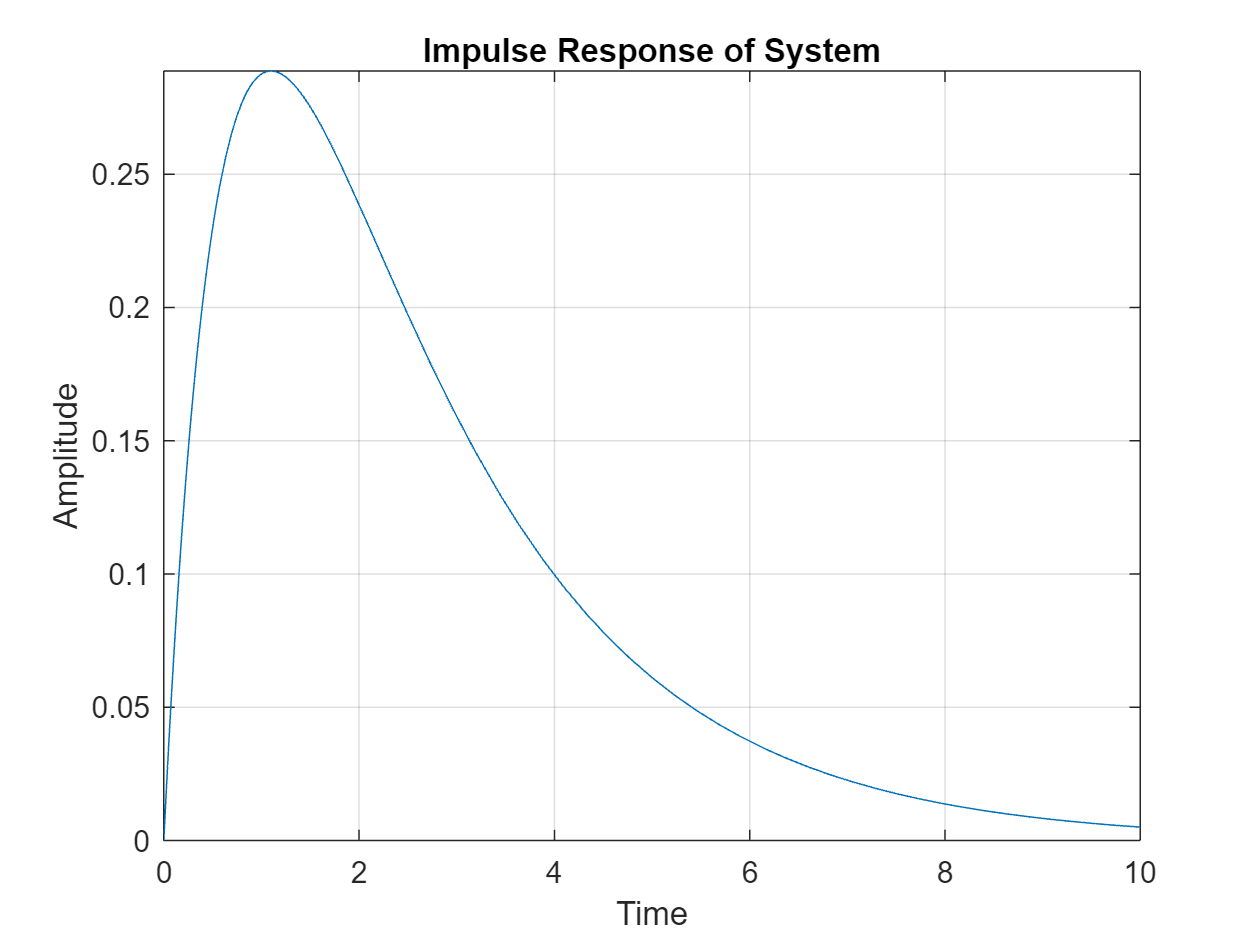

% --Generating Transfer Function
    a = 0.5;
    b = 1.5;
    closed_loop_tf = (a*b)/(a*b + a*s + b*s + s^2);

% --Calculate inverse laplace
    closed_loop_response = ilaplace(closed_loop_tf);

% --Plot response
    fplot(closed_loop_response)
    title('Impulse Response of System')
    xlim([0 10])
    hold on
    grid on
    xlabel('Time')
    ylabel('Amplitude')

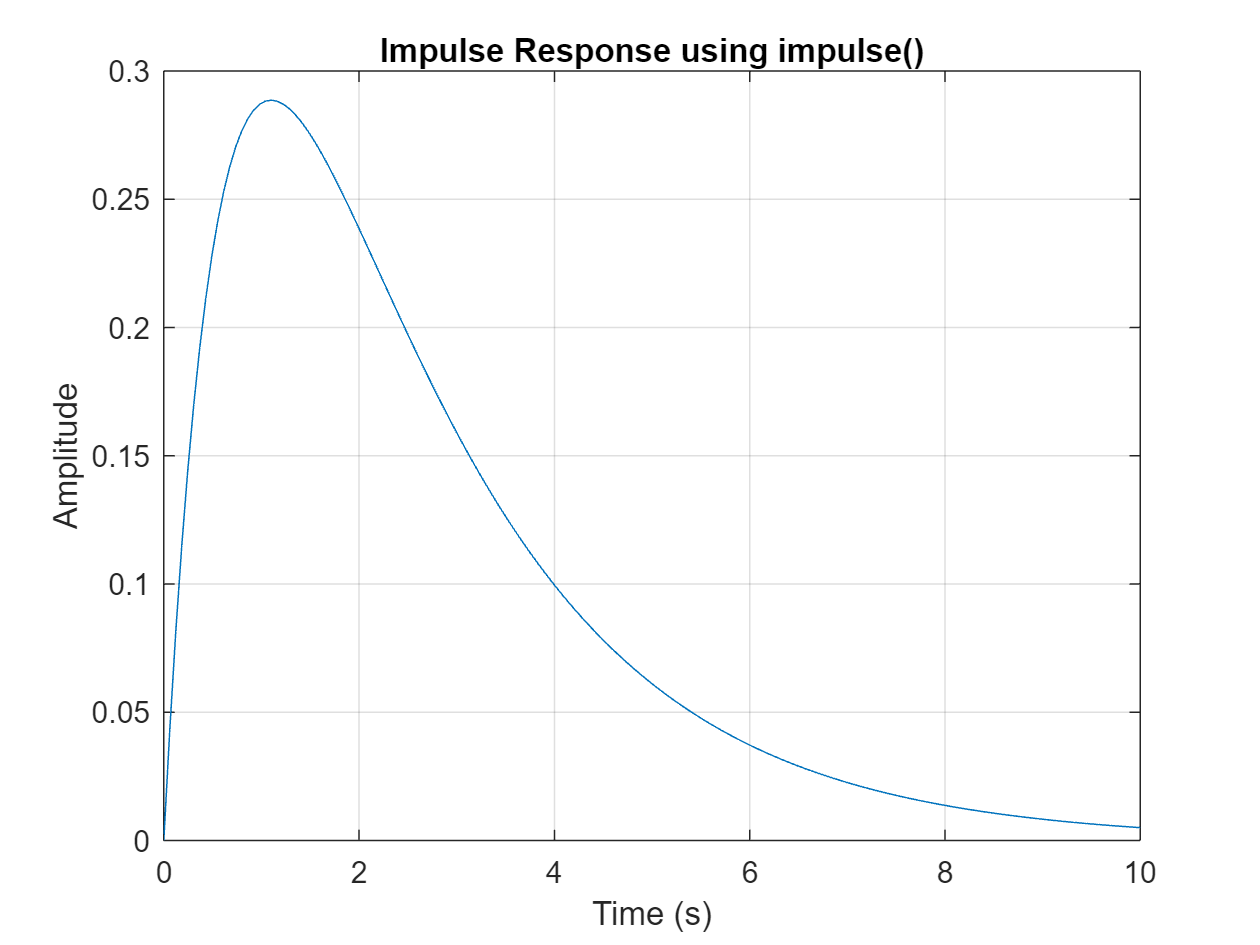


% --Creating tf object
    num = [0 0 a*b];
    denom = [1 a+b a*b];
    closed_loop_tf = tf(num,denom);
    
% --Using the impulse function
    [Y,T] = impulse(closed_loop_tf, 10);

% --Plot Response
    figure()
    plot(T,Y)
    xlabel('Time (s)')
    ylabel('Amplitude')
    title("Impulse Response using impulse()")
    grid on

Both responses look very similar to me. Perhaps the only difference is the height of the peak, there might be a larger peak using the impulse() function that is created by MATLAB.

## Problem 4.

a)  Given the matrix:  $\mathbf{A}=\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & c & 0\\
0 & d & e
\end{array}\right\rbrack$, determine an **analytic** expression (i.e. not numerical) for the determinant of $\mathbf{A}$ 

% --Create A
    syms a b c d e
    A = [a b 0;
         0 c 0;
         0 d e];
    determinate_A = det(A)

$$determinate\_A = a\,c\,e$$

b)  Determine an analytic expression for the determinant of $\left\lbrack s\;\mathbf{I}-\mathbf{A}\right\rbrack$

% --Developing I
    syms s 
    I = eye(3);
    B = [s*I - A];
    determinate_B = det(B)

$$determinate\_B = -\left(a-s\right)\,\left(c-s\right)\,\left(e-s\right)$$

c)  Explain what kind of information each of these determinants provides.

    This can help us understand if the matrix has an inverse. If we do not have a determinant then we cannot find the inverse of the matrix. 

## Problem 5.

An "Elementary Permutation Matrix" is a matrix that contains only 1's and 0's, and there can only be one 1 in any row or column.  This kind of matrix is used to swap rows or swap columns in another matrix when it is multiplied by that matrix.

a)  Use visual inspection to determine an "Elementary Left Permutation Matrix" ${\mathbf{P}}_L$ such that the product ${\mathbf{P}}_L \mathbf{A}$ swaps rows 2 and 3 of the $\mathbf{A}$ matrix from Problem 4.


$${\mathbf{P}}_L \mathbf{A}=\left\lbrack \begin{array}{ccc}
 &  & \\
 &  & \\
 &  & 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & c & 0\\
0 & d & e
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & d & e\\
0 & c & 0
\end{array}\right\rbrack$$


% --Define PL
    PL = [1 0 0;
          0 0 1;
          0 1 0];

% --Proof
    PLA = PL*A

$$PLA = \left(\begin{array}{ccc} a & b & 0\\ 0 & d & e\\ 0 & c & 0 \end{array}\right)$$

b)  Use visual inspection to determine a "Elementary Right Permutation Matrix" ${\mathbf{P}}_R$ such that the product $\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R$ swaps columns 2 and 3 of the ${\mathbf{P}}_L \mathbf{A}$ matrix.


$$\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R =\left\lbrack \begin{array}{ccc}
a & b & 0\\
0 & d & e\\
0 & c & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
 &  & \\
 &  & \\
 &  & 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
a & 0 & b\\
0 & e & d\\
0 & 0 & c
\end{array}\right\rbrack$$


% --Define PR
    PR = [1 0 0;
          0 0 1;
          0 1 0];

% --Proof
    PLAPR = PLA*PR

$$PLAPR = \left(\begin{array}{ccc} a & 0 & b\\ 0 & e & d\\ 0 & 0 & c \end{array}\right)$$

c)  Compute the determinants of ${\mathbf{P}}_R$ and ${\mathbf{P}}_L$

% --Determinate of PR
    det_PR = det(PR)

det_PR = -1


% --Determinate of PL
    det_PL = det(PL)

det_PL = -1

d)  Compute the determinant of $\left({\mathbf{P}}_L \mathbf{A}\right)\;{\mathbf{P}}_R$

% --Determinate of PLAPR
    det_PLAPR = det(PLAPR)

$$det\_PLAPR = a\,c\,e$$

e)  Compare the result from 5d) to the product $\left|{\mathbf{P}}_L \right|\times \left|\mathbf{A}\right|\times \left|{\mathbf{P}}_R \right|$

% --Computing cross product
    cross_PLA = cross(PL,A);
    cross_PLAPR = cross(cross_PLA,PR)

$$cross\_PLAPR = \left(\begin{array}{ccc} 0 & b & 0\\ 0 & c & 0\\ 0 & 0 & e \end{array}\right)$$